kappa_int = 0.2e6;
kappa_ext = 1.2e6;
kappa_tot = kappa_int + kappa_ext;
Z_0 = 50;
Z = 4*Z_0/pi;
kerr = -.5e6;
phi_zp = 0.176;
domega_dphi = 31.06e6 % at that bias point, units of rads/s/flux_quantum

domega_dphi = 31060000

detuning_array = linspace(-5e6, 5e6, 100);
flux_quanta_drive = linspace(0,.1, 90); %units of flux quanta
delta_pump = flux_quanta_drive.^2*pi^2/phi_zp^2 * kerr;%1/4/Z* flux_quanta_drive.^2*kerr;
epsilon = 1/2*domega_dphi.*flux_quanta_drive;

[detuning_mesh, epsilon_mesh] = meshgrid(detuning_array, epsilon);
[~, delta_pump_mesh] = meshgrid(detuning_array, delta_pump);

n_oscillations = 1/kerr.*(-detuning_mesh + sqrt(epsilon_mesh.^2 - kappa_tot^2/4));
n_oscillations_other_root = 1/kerr.*(-detuning_mesh - sqrt(epsilon_mesh.^2 - kappa_tot^2/4));
n_oscillations_complex = n_oscillations;
n_oscillations(abs(imag(n_oscillations))> 1e-6) = 0;
n_oscillations = real(n_oscillations);
n_oscillations(n_oscillations < 0) = 0;

n_oscillations_other_root(abs(imag(n_oscillations_other_root))> 1e-6) = 0;
n_oscillations_other_root = real(n_oscillations_other_root);
n_oscillations_other_root(n_oscillations_other_root < 0) = 0;

n_oscillations_with_pump_detuning = 1/kerr.*(-detuning_mesh - delta_pump_mesh + sqrt(epsilon_mesh.^2 - kappa_tot^2/4));
n_oscillations_other_root_with_pump_detuning = 1/kerr.*(-detuning_mesh - delta_pump_mesh- sqrt(epsilon_mesh.^2 - kappa_tot^2/4));
n_oscillations_complex_with_pump_detuning = n_oscillations_with_pump_detuning;
n_oscillations_with_pump_detuning(abs(imag(n_oscillations_with_pump_detuning))> 1e-6) = 0;
n_oscillations_with_pump_detuning = real(n_oscillations_with_pump_detuning);
n_oscillations_with_pump_detuning(n_oscillations_with_pump_detuning < 0) = 0;

n_oscillations_other_root_with_pump_detuning(abs(imag(n_oscillations_other_root_with_pump_detuning))> 1e-6) = 0;
n_oscillations_other_root_with_pump_detuning = real(n_oscillations_other_root_with_pump_detuning);
n_oscillations_other_root_with_pump_detuning(n_oscillations_other_root_with_pump_detuning < 0) = 0;

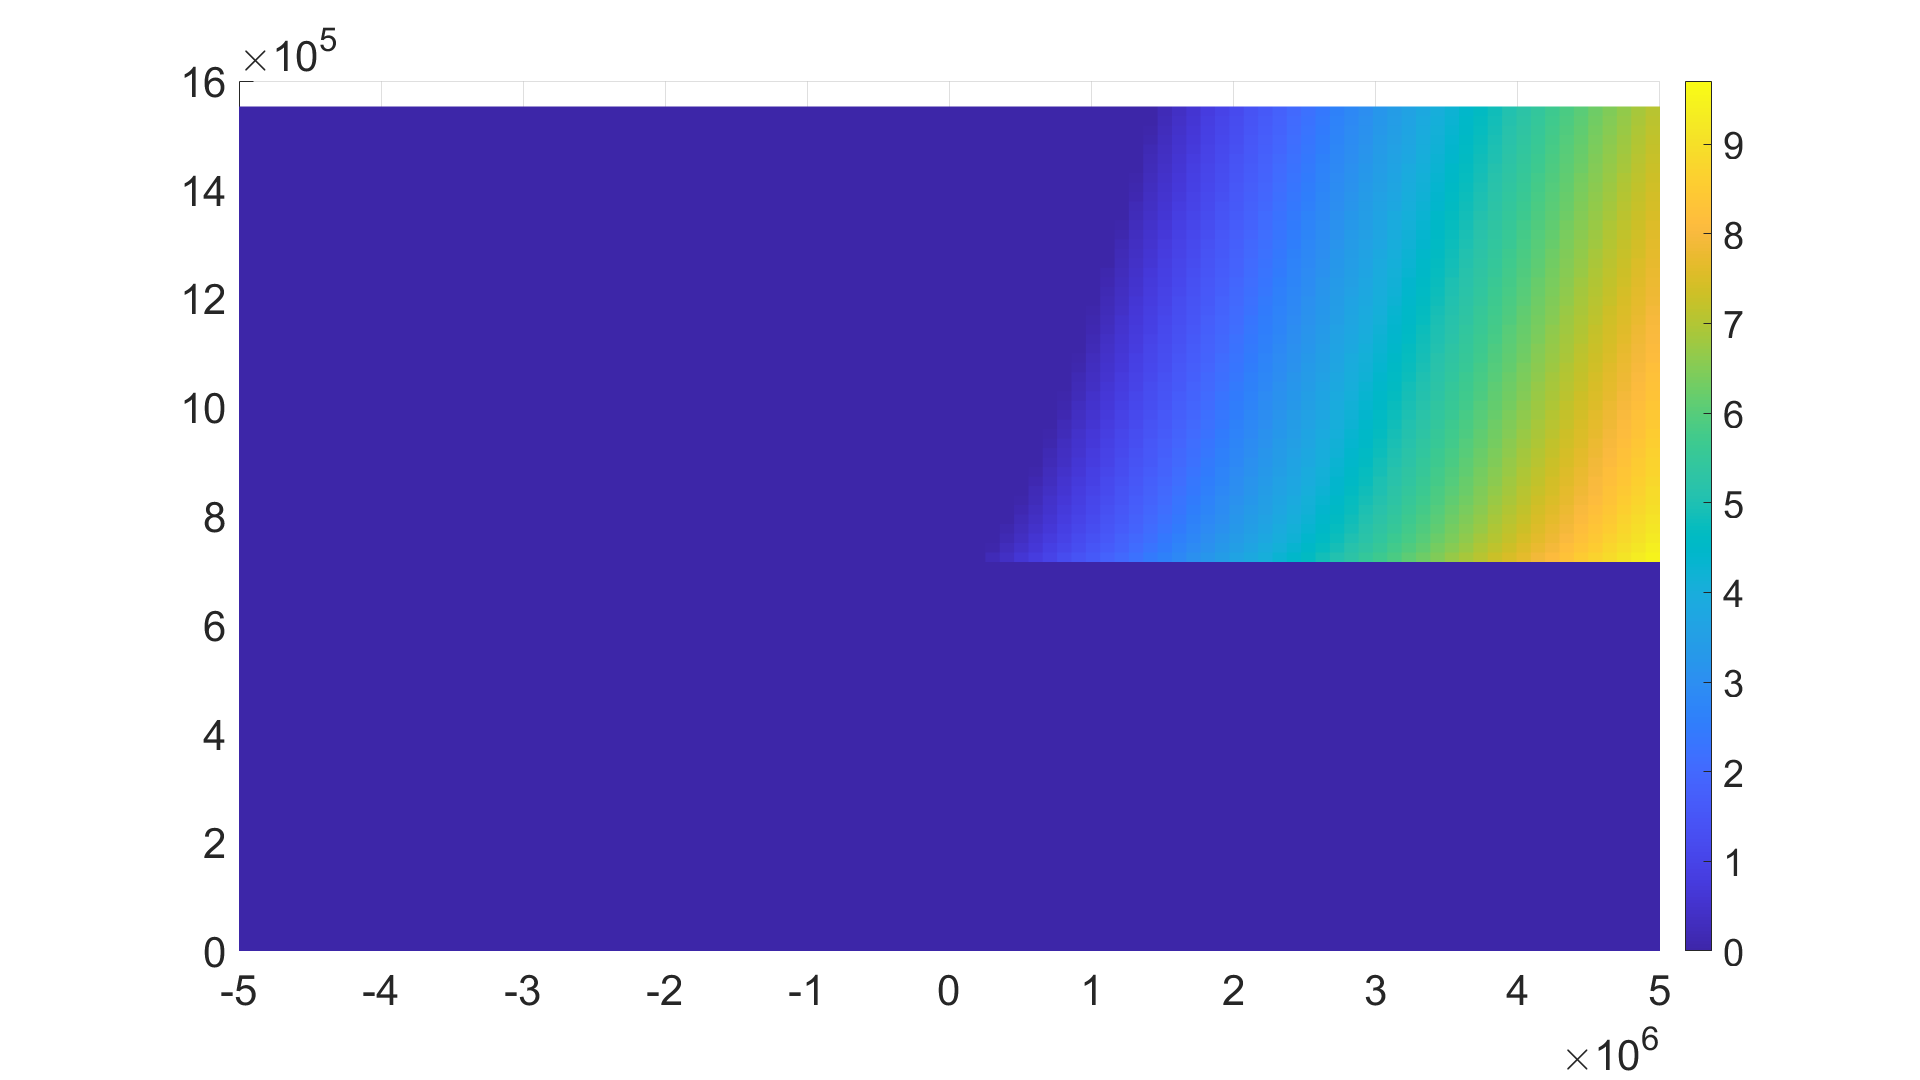

figure
r=surf(detuning_array, abs(epsilon), n_oscillations);
set(r,'LineStyle','none');
view(0,90)
colorbar

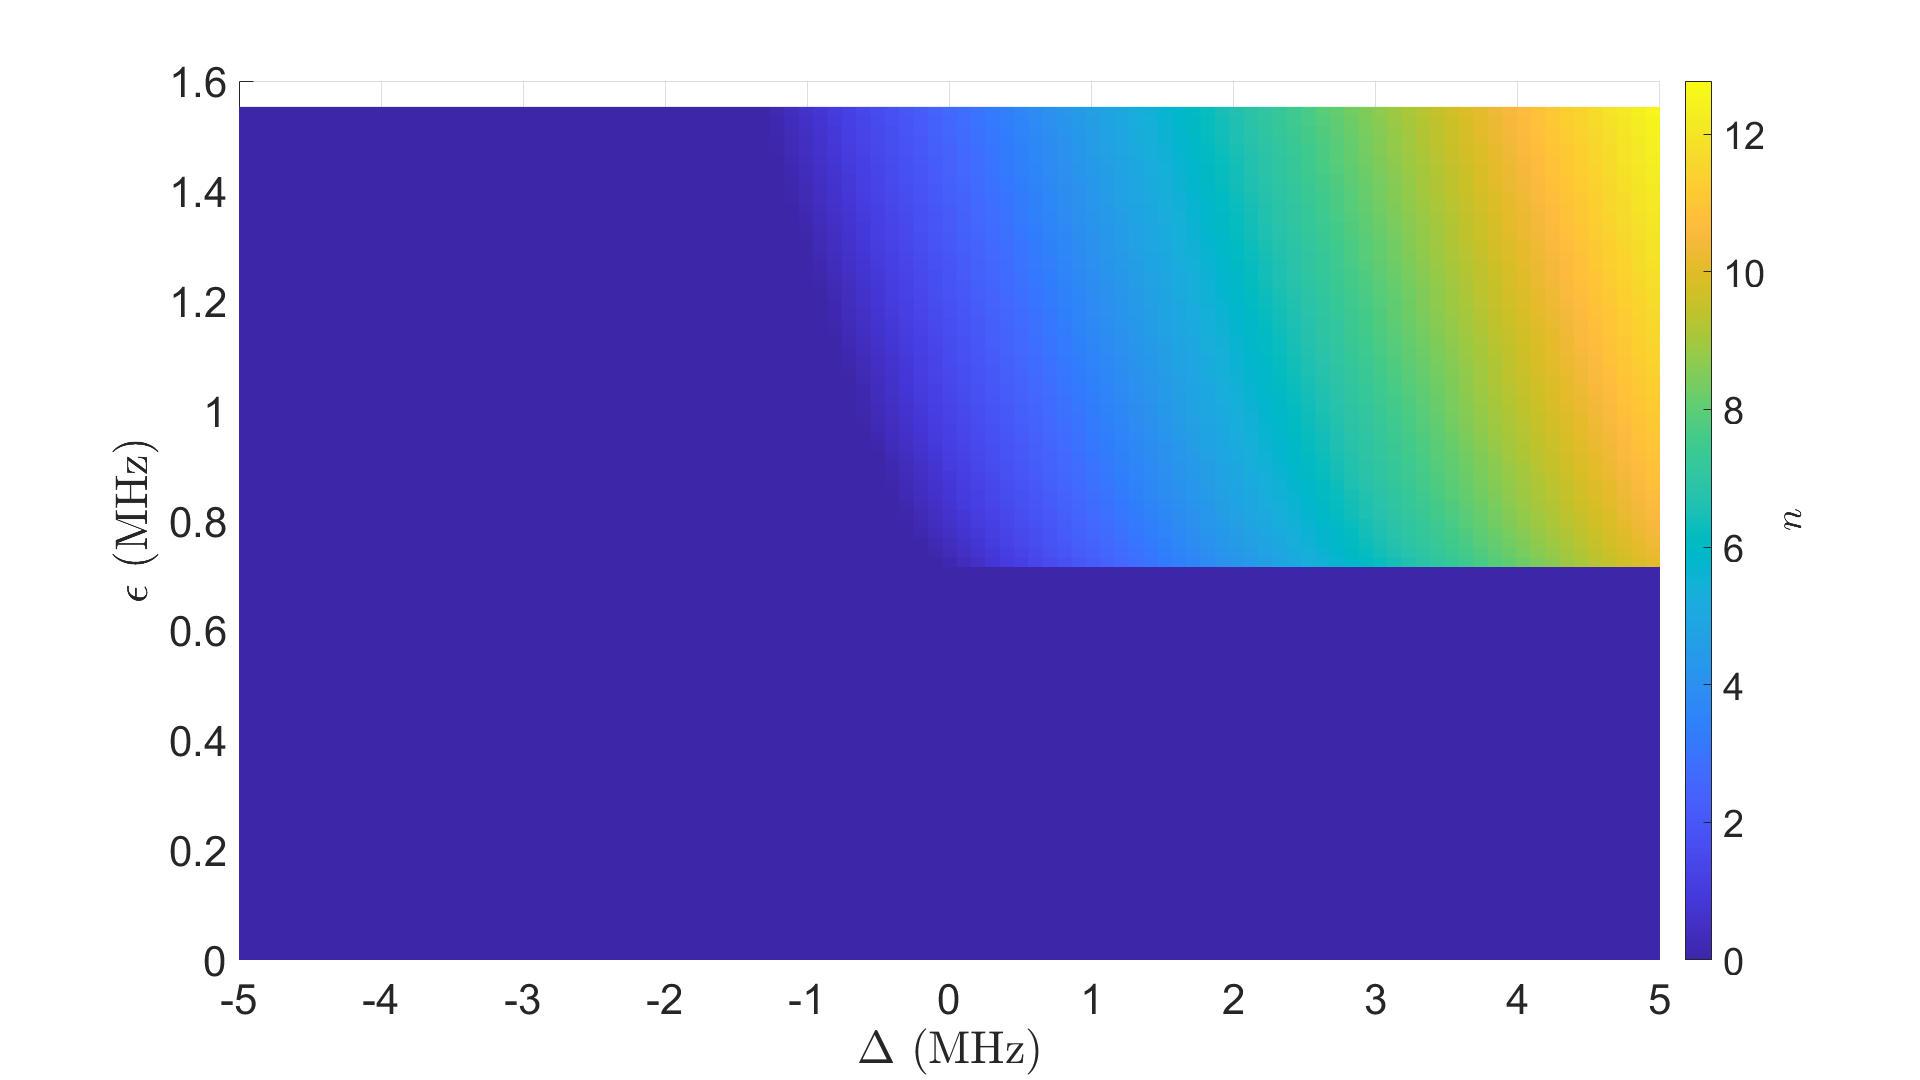

figure
r=surf(detuning_array/1e6, abs(epsilon)/1e6, n_oscillations_other_root);
set(r,'LineStyle','none');
view(0,90)
c = colorbar;
hL = ylabel(c,'$n$', 'interpreter', 'latex');     
set(hL,'Rotation',90);
clear c ...
      hL
xlabel('$\Delta$ (MHz)', 'interpreter', 'latex', 'FontSize',56)
ylabel('$\epsilon$ (MHz)', 'interpreter', 'latex', 'FontSize', 56)

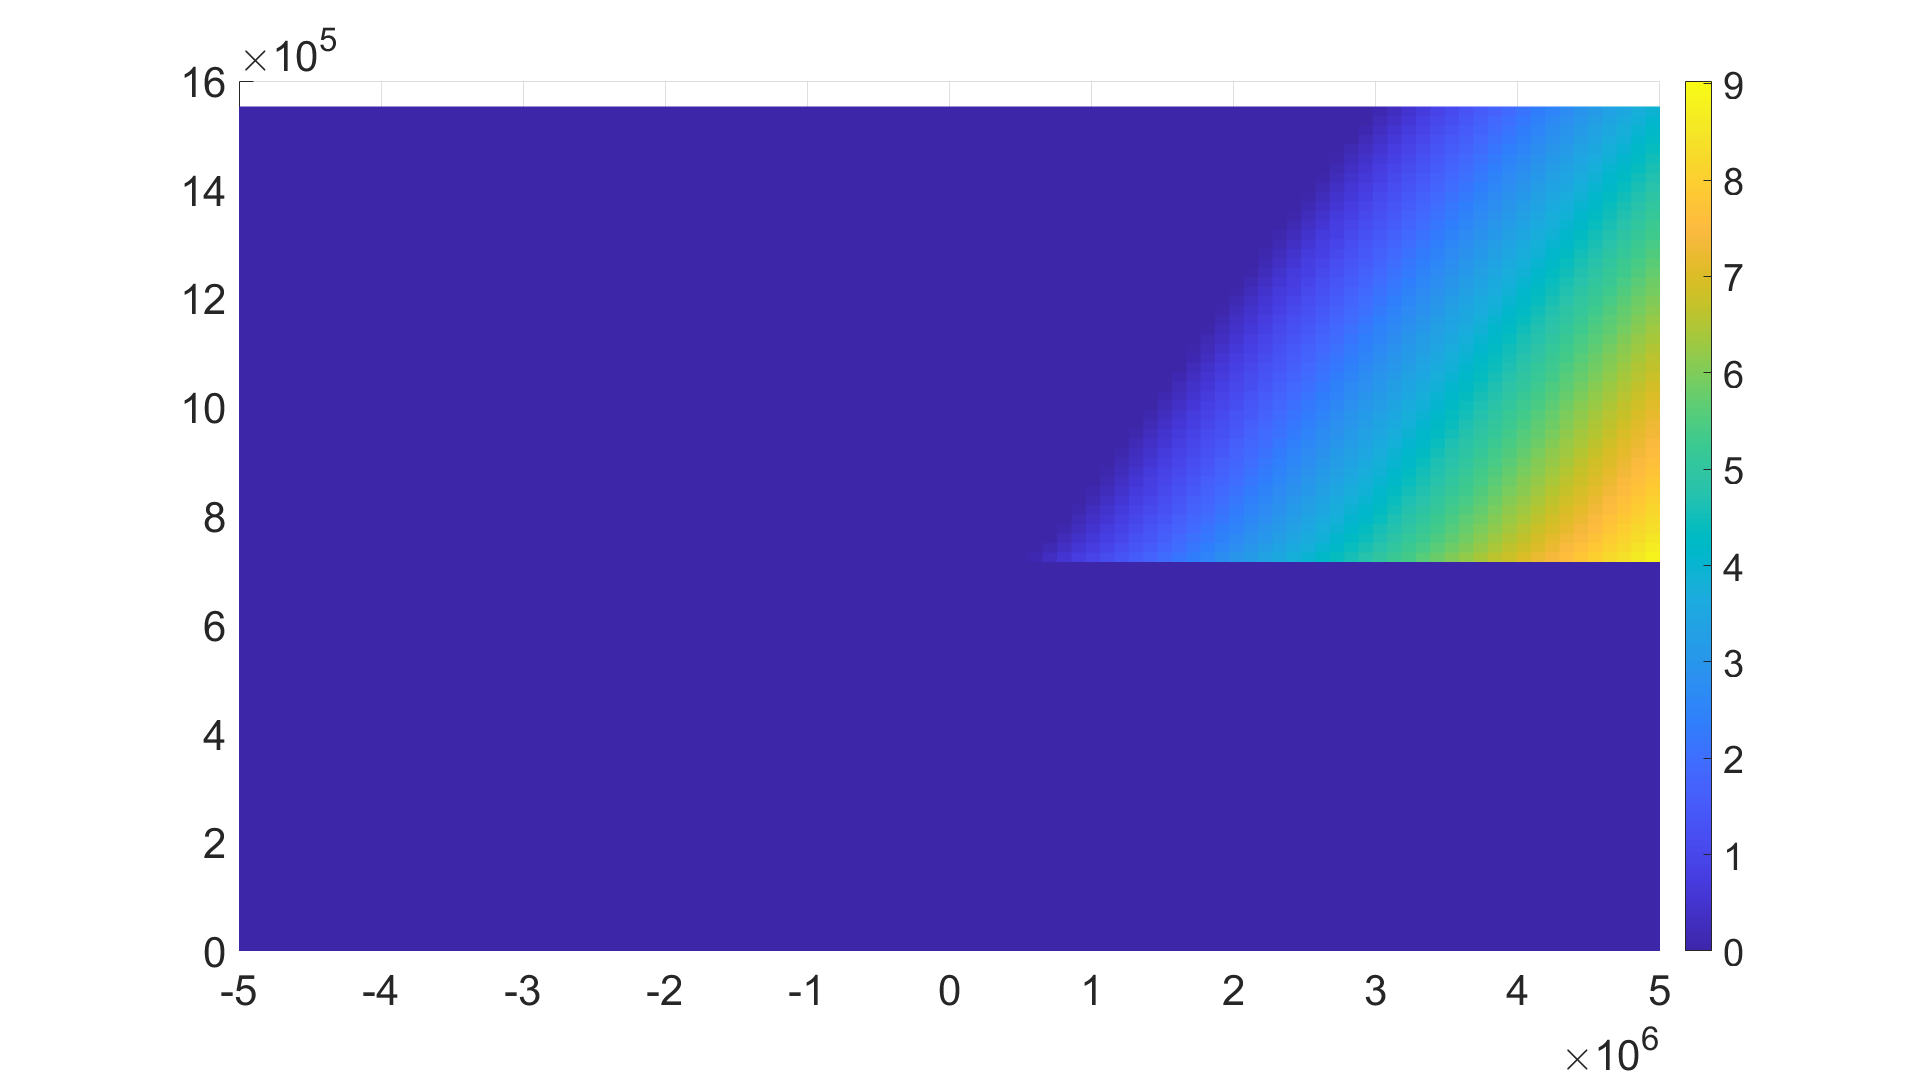

figure
r=surf(detuning_array, abs(epsilon), n_oscillations_with_pump_detuning);
set(r,'LineStyle','none');
view(0,90)
colorbar

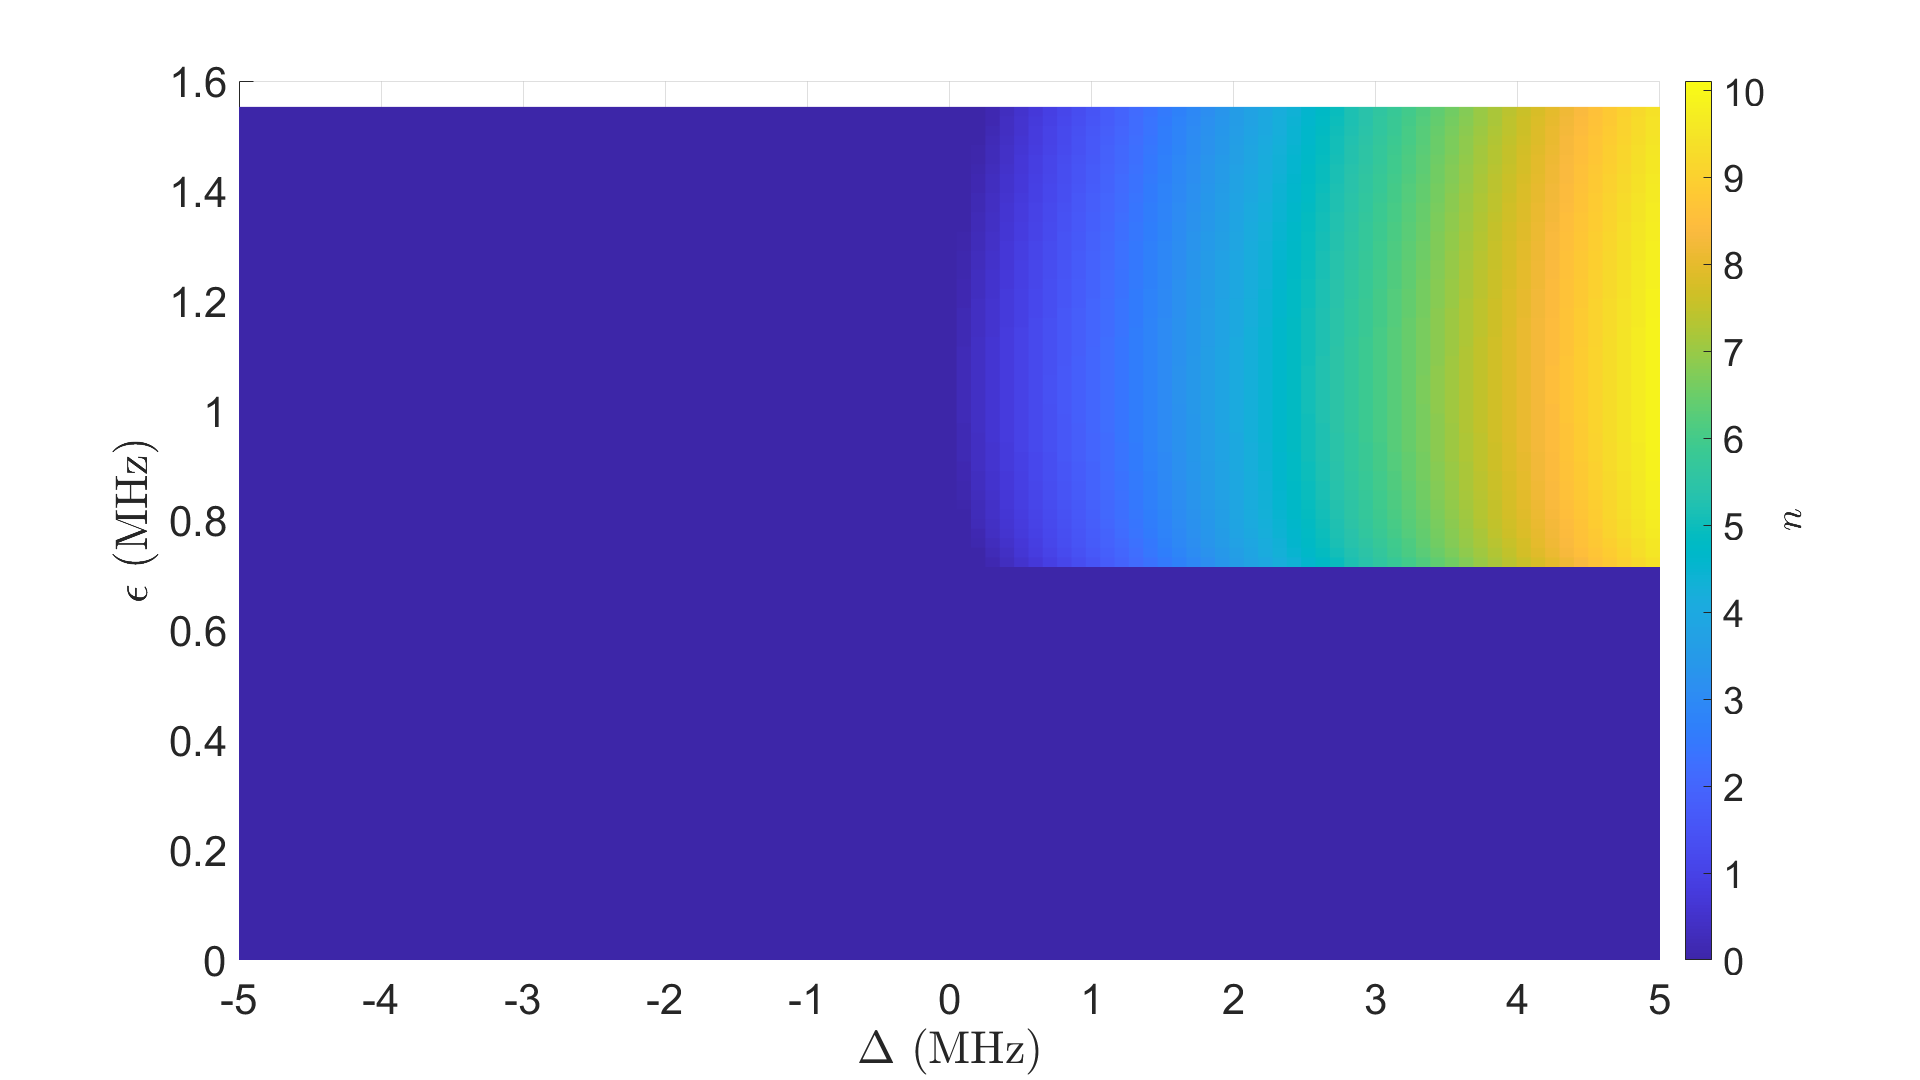

figure
r=surf(detuning_array/1e6, abs(epsilon)/1e6, n_oscillations_other_root_with_pump_detuning);
set(r,'LineStyle','none');
view(0,90)
c = colorbar;
hL = ylabel(c,'$n$', 'interpreter', 'latex');     
set(hL,'Rotation',90);
clear c ...
      hL
xlabel('$\Delta$ (MHz)', 'interpreter', 'latex', 'FontSize',56)
ylabel('$\epsilon$ (MHz)', 'interpreter', 'latex', 'FontSize', 56)